# **Bases para transformacion en a frequencia**

**Frequencia de señal**


$$\begin{array}{l}
f=5\;\textrm{Hz}\\
\omega =2\pi 5\;\frac{\textrm{rad}}{s}
\end{array}$$


**Frequencia de muestro **


$$f_s =100\;\textrm{Hz}$$
   

**Tiempo de observacion**


$$T_{\textrm{obs}} :-1\le t\le 1$$


Creamos una señal senosoidal y la graficamos

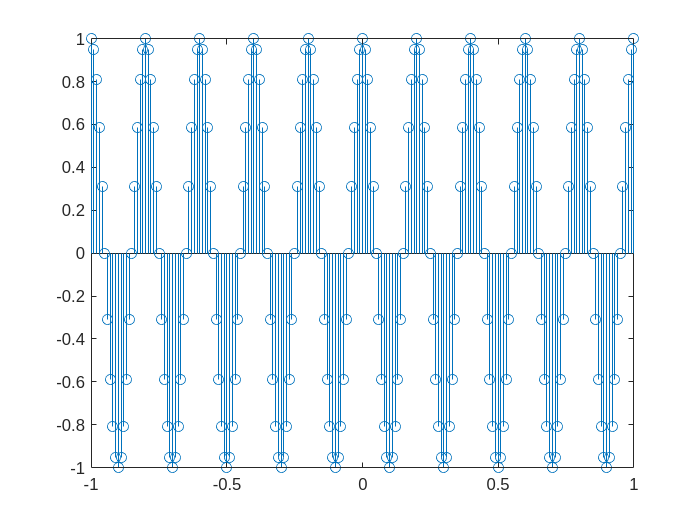

fs   = 100;
time = -1:1/fs:1;
x    = cos(2*pi*5*time);
stem (time,x)

Pasamos a poner la señal en el dominio de la frequencia junto con su grafica 

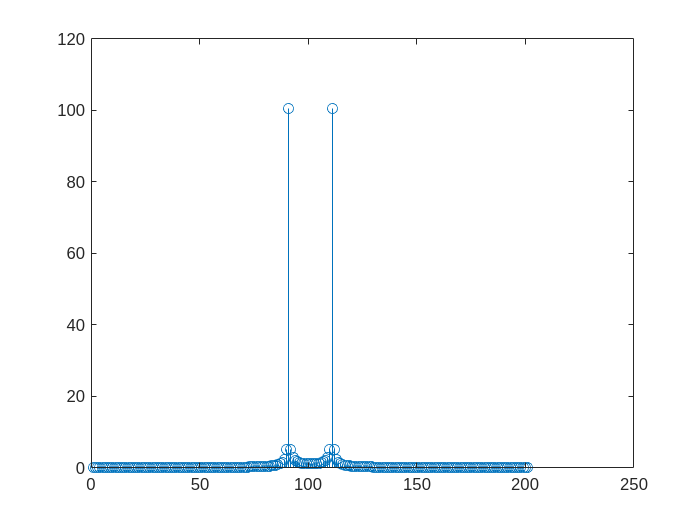

y=ttof(x);
stem(abs(y))

Como podemos observa las graficas no estan totalmente alieandas a $f=5\textrm{Hz}$

## ¿Como hago un eje adecuado de frequencia para la grafica que quiero presentar?

Se tiene considerar la maxima frequency observable por el teorema de Nyquist. 

**Maxima frequencia observable**


$$\frac{f_s }{2}=50\;\textrm{Hz}$$


Por otro lado necesitamos definir una resolucion adecuada en frecuencia. El maximo tiempo de observacion refleja la resolucion frequencial. La maxima venta de observacion frequencial visible $\frac{1}{T_{\textrm{obs}} }$ . Dado que necesitamos tanto el lado negativo 

de la frequencia como el positivo nuestro rango va de $\left\lbrack -\frac{f_s }{2},\frac{f_s }{2}\right\rbrack$ con una resolucion $\frac{1}{T_{\textrm{obs}} }$ . Recordad que $T_{\textrm{obs}} :-1\le t\le 1\;$por lo tanto $T_{\textrm{obs}} =2$

**Nota:** SI $T_{\textrm{obs}\;} \;$es mayor entonces tendremos mejor resolucion en frequencia. 

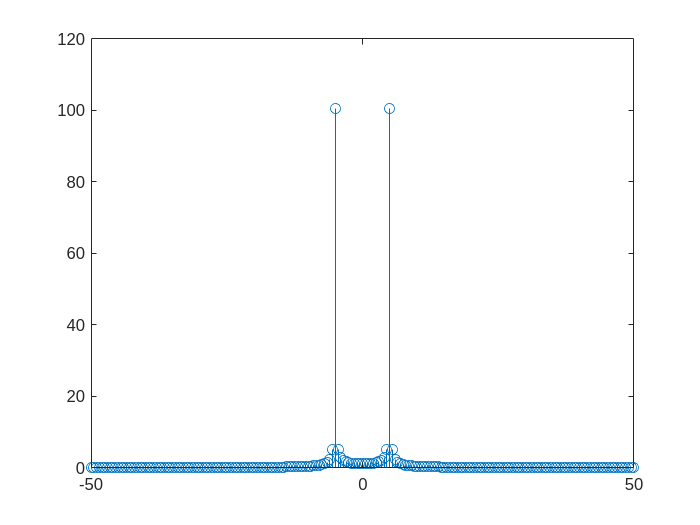

step = max(time)-min(time); %Longitud de la venta de obervacion en tiempo. 
freq = -fs/2:1/step:fs/2;
stem(freq,abs(y))

Finalmente las frequencias se ven reflejadas en [-5,5] Hz

## ¿Por que aparecen los lobulos?

- Lo que se esta graficando no es una cosenodial pura, si no que se esta graficando junto con una ventana cuadrada de 2 segundos. En frequencia esto es la convolucion de una $\textrm{sinc}\left(x\right)*\left\lbrack \delta \left(t\right)+\delta \left(-t\right)\right\rbrack$

- El problema se genera por que no pasamos la señal periodica en forma estricta. El valor mas chico de la senoidal es igual al mas grande, y en sentido computacional esto es como si la muestra mas grande fuera parte del conjunto de valores que conforman un periodo $T_n$ sin embargo no es asi, ya que la ultima muestra representa parde del periodo siguiente $T_{n+1}$

x(1) == x(end)

ans = logical
   1


Quitamos la ultima muestra tanto para tiempo como frequencia

x(end)    = [];
y=ttof(x);
freq(end) = [];
x(1) == x(end) % demostracion de igualdad

ans = logical
   0


Graficamos

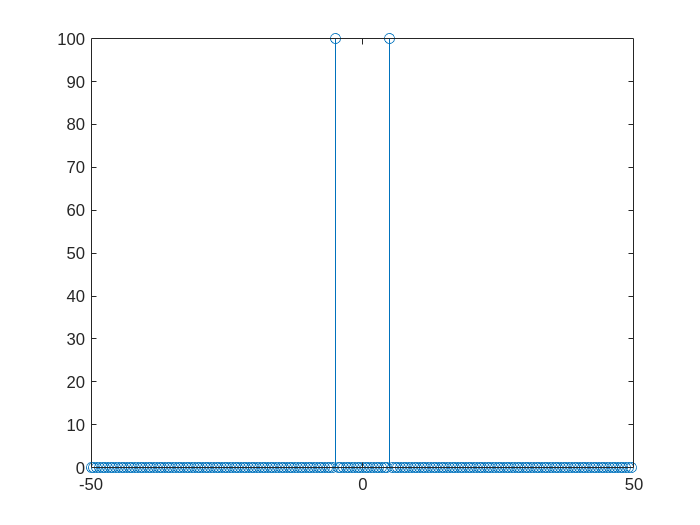

stem(freq,abs(y))

Finalmente tenemos una transformada discreta de fourier limipia. 